clear all
close all
clc

% Notch Filter Design
Fs = 10e3;
Ts = 1/Fs;

% Specify
M = 128; % order of filter
N = M+1; % number of filter conditions

% Notch Frequency
fo = 1e3*Ts;
wo = 2*pi*fo;

% Notch width
alfa = 10*2*pi*Ts;

% Find the P matrix
P = zeros(N);
q = zeros(N,1);

% Part1
dw = pi/200; % Frequency domain sampling
w = [0:dw:(wo-alfa/2)]';
nM = [0:(N-1)]';
U = cos(nM*w'); % vectors for every w between 0 to wo-alpfa/2
for n1 = 1:N
    for n2 = 1:N
        P(n1, n2) = P(n1, n2)+trapz(U(n1,:).*U(n2,:))*dw;
    end
end
q = q-2*trapz(U,2)*dw;

% Part2
W = 100; % Weight of the notch part
Epsi = 0.001;
dw = pi/500; % Frequency domain sampling more samples in the stop band
w = [(wo-alfa/2):dw:(wo+alfa/2)]';
nM = [0:(N-1)]';
U = cos(nM*w'); % vectors for every w between 0 to wo-alpfa/2
for n1 = 1:N
    for n2 = 1:N
        P(n1, n2) = P(n1, n2)+trapz(U(n1,:).*U(n2,:))*dw;
    end
end
q = q-2*W*Epsi*trapz(U,2)*dw;

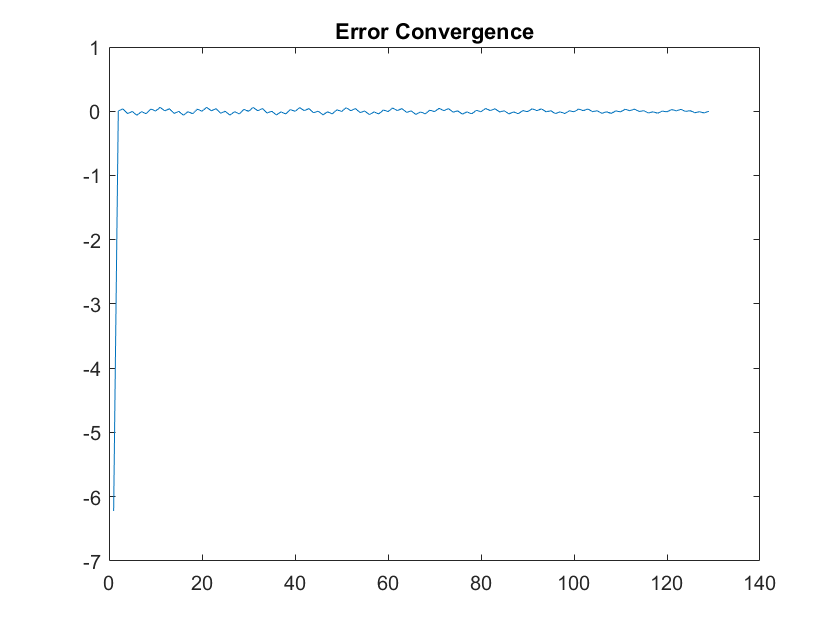

% Part3
dw = pi/200; % Frequency domain sampling
w = [(wo+alfa/2):dw:pi]';
nM = [0:(N-1)]';
U = cos(nM*w'); % vectors for every w between 0 to wo-alpfa/2
for n1 = 1:N
    for n2 = 1:N
        P(n1, n2) = P(n1, n2)+trapz(U(n1,:).*U(n2,:))*dw;
    end
end
q = q-2*trapz(U,2)*dw;
plot(q)
title("Error Convergence")

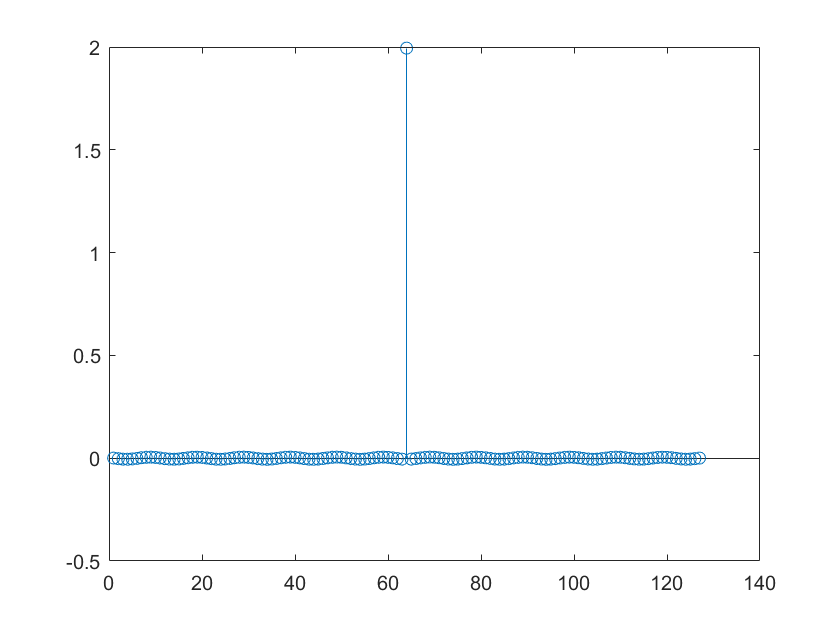

% Solve for minimizing this (a'*P*a+q'*a+r)

a = -P\q;

% map back to the filter coefficients

for k = 1:M/2-1
    h(M/2-k) = a(k+1)/2;
    h(M/2+k) = a(k+1)/2;
end
h(M/2) = a(1);

figure(1)
stem(h), shg

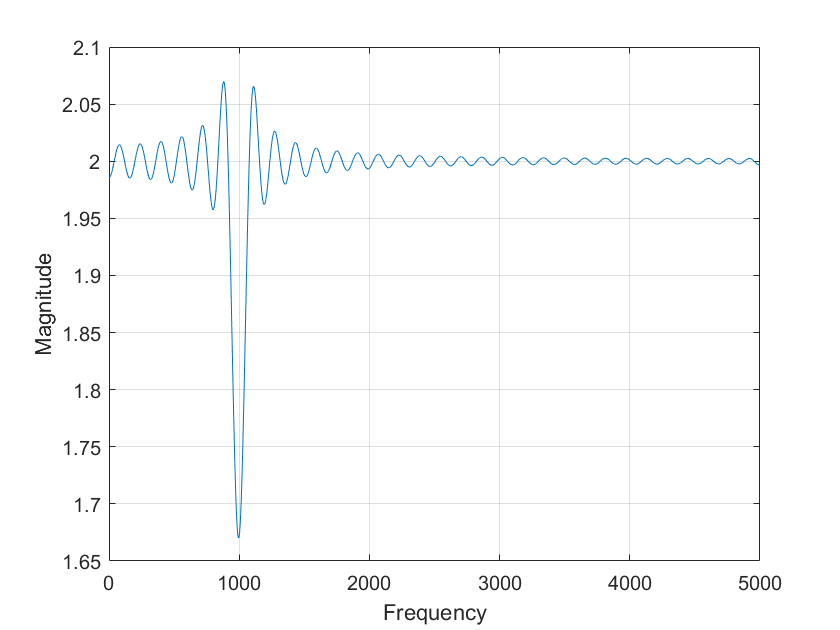

figure(2)
F = linspace(0, Fs/2, 2000);
H = freqz(h, 1, F, Fs);
plot(F, abs(H)), grid on
ylabel('Magnitude')
xlabel('Frequency')

shg
